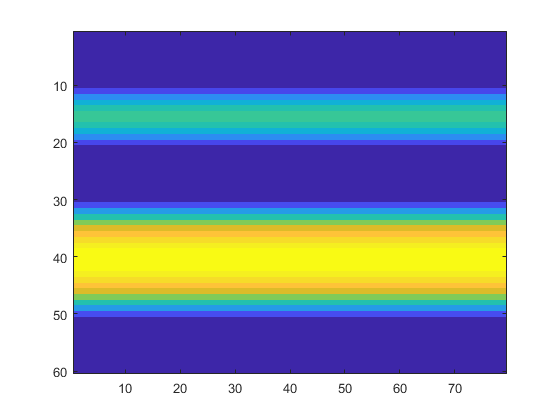

% p0=dlmread('p0.txt');
% [n,m]=size(p0);
% v=zeros(70,n,m);
% for i=0:70
% v(i+1,:,:)=load(['p' num2str(i) '.txt']);
% end
% 
% imagesc(p0);
% for j=1:70
%    tmp=squeeze(v(j,:,:));
%    figure;
%    imagesc(tmp);
%    colorbar;
% end

u0=dlmread('u198.txt');
[nu,mu]=size(u0);
u=zeros(499,nu,mu);
for i=0:499
u(i+1,:,:)=load(['u' num2str(i) '.txt']);
end

imagesc(u0);

for j=1:499
    tmp=squeeze(u(j,:,:));
    h=figure(j);
    imagesc(tmp);
    colorbar;
    filename=strcat('fig_',num2str(j));
    saveas(h,filename, 'png');
    close(h);
end

% p0=dlmread('p0.txt');
% [nu,mu]=size(p0);
% p=zeros(3,nu,mu);
% for i=0:3
% p(i+1,:,:)=load(['p' num2str(i) '.txt']);
% end
% 
% imagesc(p0);
% for j=1:3
%     tmp=squeeze(p(j,:,:));
%     h=figure(j);
%     imagesc(tmp);
%     colorbar;
%     filename=strcat('figp_',num2str(j));
%     saveas(h,filename, 'png');
%     close(h);
% end
 
